UGR_st.name='UGR';
UGR_st.lat=37.1640014648;
UGR_st.lon=-3.6050000191;
UGR_st.alt=680;
UGR_st.env='con';
UGR_st.footp='U';


UGR_rd=read_betsy('ugr_2004_2018',UGR_st.name);
namesok=fieldnames(UGR_rd);
Cb=startsWith(namesok,["Bs", "Bbs","U","T_","P_","T0","P0"]);
namesCb=namesok(Cb);
for i=1:length(namesCb)
    ind=UGR_rd.(namesCb{i})==99999.999;
UGR_rd.(namesCb{i})(ind)=NaN;
end


datevec(UGR_rd.Time(1))

ans =         2006           1           2           0           0           0

datevec(UGR_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(UGR_rd.U_S,[5 50 95])

ans =    14.0250   28.9500   46.3375

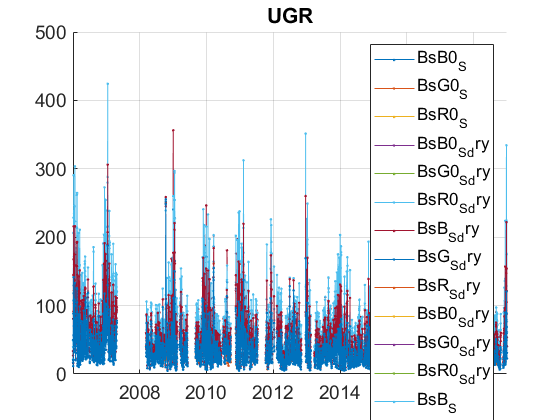

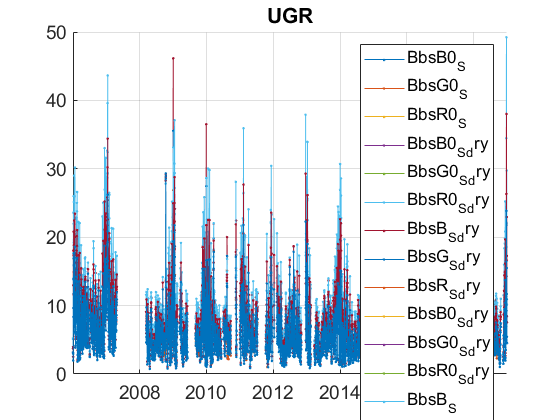

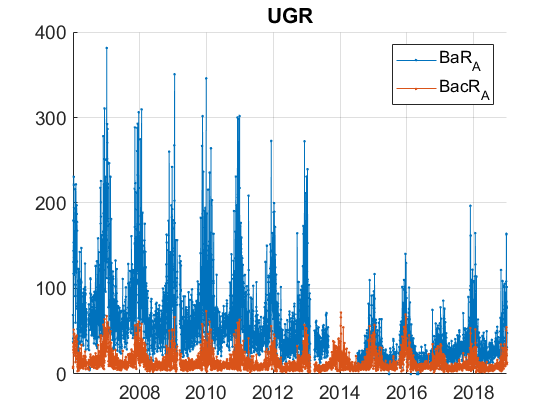

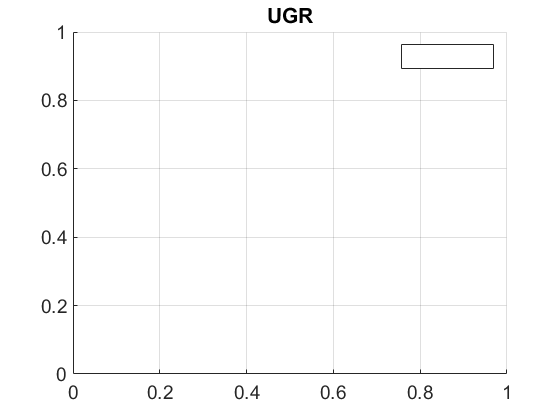

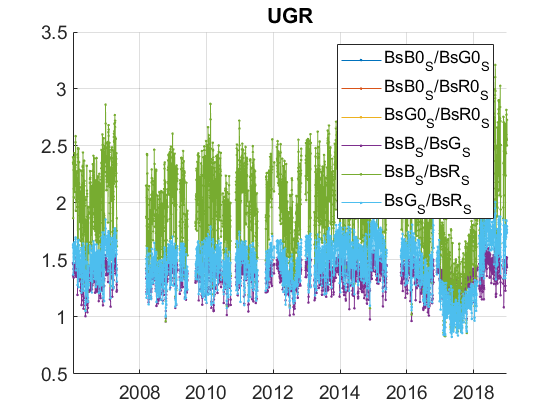

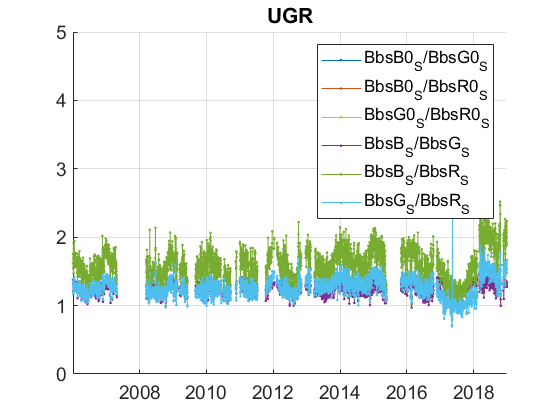

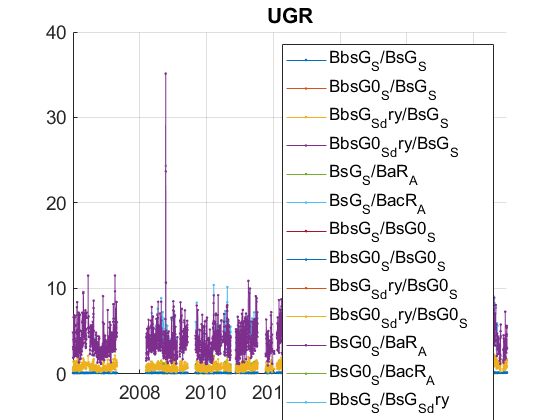

plotFigControl(UGR_rd, UGR_st.name);

% 1 size cut, ok
% sc: ok, max in winter, no negatives
    


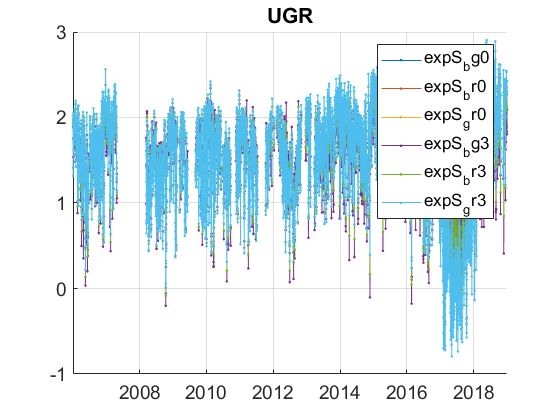

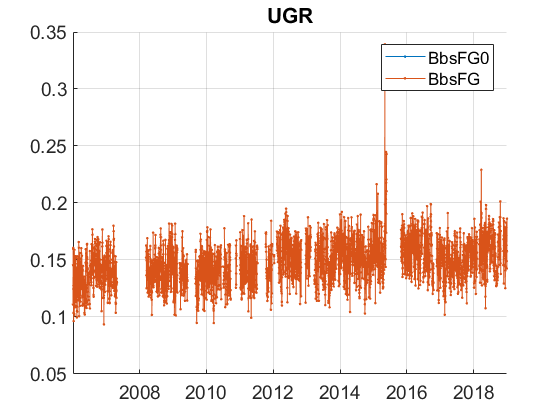

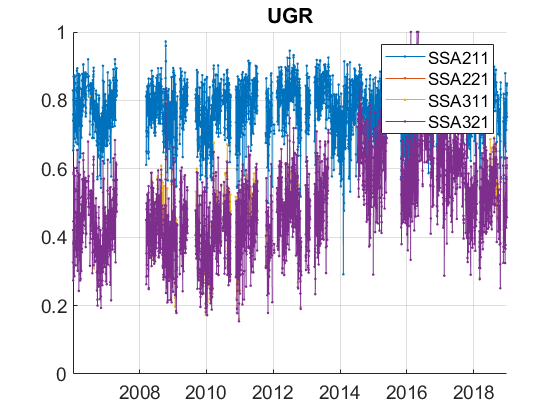

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
UGR_cal=compute_exp_SSA(UGR_rd,lambdaSC, lambdaAE);
% SSA=UGR_rd.BsG_S./(UGR_rd.BsG_S+UGR_rd.BacR_A);
% hold on;
% plot(UGR_rd.Time,SSA,'.G')
plotFigControl_cal(UGR_cal, UGR_st.name);

%Questions:
%problems:

%SC: data in 2007 seems to be higher (both minima and maxima)
%sc: all ratio between wavelengths (but particularly with the red one) show a strange decrease in 2017 and then higher values in 2018. This is also visible in the exponent. Can you explain/correct it ?
%sc: the backscatter fraction (green) has higher values in May 2015 just before a hole. Should I invalidate them ?

%ABS: the time series BacR_A is ok
% the time series called BaR_A has problem from April 2013. What happened? From which instrument


UGR_tr=UGR_rd;
UGR_tr.y=year(UGR_tr.Time);
%enleve une valeur de 2019
UGR_tr=UGR_tr(1:end-1,:);
% begin at the beginning of a year: 2006
%end 2018

P=timerange('2006-01-01','2019-01-01');
UGR_tr=UGR_tr(P,:);
%all Bs..0_ are empty: to delete
%use BacR, and delete BaR
names=fieldnames(UGR_tr);
c=contains(names,["0","Q"]) | startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"X";"Z";"BaR"]);
N=names(c);
for i=1:length(N)
    UGR_tr.(N{i})=[];
end
% change in U --> analyse of dry trends

%scat: 2006-2007 doubt: wait answer probably ok, 2007-2008 lev2 to be send (wait), 2017: doubt, probably ok, 2018 to invalidate
%intercomparison 9 feb-3 March 2018:already done, not in the time series
%Bbs: invalidate from 6 Mai -31 Mai 2015to delete:
P1=timerange('2015-05-06','2015-05-31');
names=fieldnames(UGR_tr);
c= startsWith(names,["Bbs"]);
N=names(c);
for i=1:length(N)
    UGR_tr.(N{i})(P1)=NaN;
end

%abs: use BacR (delete BaR) 2006-2018

% correct abs to green wavelength for SSA calculation
UGR_tr.BacR_A=UGR_tr.BacR_A.*(637/550);
%compute deribed values
UGR_cal2=compute_exp_SSA(UGR_tr,lambdaSC, lambdaAE);
%compute dry exp, BbsF and SSA:
UGR_cal2.expS_bg3_dry=UGR_cal2.expS_bg2;
UGR_cal2.expS_bg2=[];
UGR_cal2.BbsFG_dry=UGR_cal2.BbsFG2 ;
UGR_cal2.BbsFG2=[];
UGR_cal2.SSAG_dry=UGR_tr.BsG_S_dry./(UGR_tr.BsG_S_dry+UGR_tr.BacR_A);


UGR_tr=outerjoin(UGR_tr, UGR_cal2);

% no trend on B and R
UGR_tr.BsB_S=[];
UGR_tr.BsR_S=[];
UGR_tr.BbsB_S=[];
UGR_tr.BbsR_S=[];
UGR_tr.BsB_S_dry=[];
UGR_tr.BsR_S_dry=[];
UGR_tr.BbsB_S_dry=[];
UGR_tr.BbsR_S_dry=[];
% expS: december 2016 to 2018 to invalidate + no trend with R
UGR_tr.expS_gr3=[];
UGR_tr.expS_br3=[];
UGR_tr.expS_gr2=[];
UGR_tr.expS_br2=[];
P2=timerange('2017-01-01','2019-01-01');
UGR_tr.expS_bg3(P2)=NaN;
UGR_tr.expS_bg3_dry(P2)=NaN;

UGR_result= all_trend_STN(UGR_tr,UGR_st); 
plot_10y_in_two(UGR_result, UGR_st);

UGR_result_D=UGR_result;